**Autor(es): Joseph Principe Pajuelo Condori**

**Fecha: 15/10/2026**

El objetivo principal de esta práctica es familiarizarse con los principales operadores morfológicos y analizar el efecto que producen el **tipo, la forma y el tamaño del elemento estructurante** sobre distintos tipos de imágenes.

close all
clear all

1) Lea la imagen en color 'autumn.tif' y muéstrela.

I_autumn = imread('autumn.tif');

2) Utilizando la función strel, cree un elemento estructurante con forma de disco de 5 píxeles de radio. 

 SE_disk5 = strel('disk', 5);

3) Erosione y dilate la imagen utilizando dicho elemento estructurante y muestre conjuntamente la imagen original y las dos imágenes resultantes. Tenga en cuenta que, en una imagen RGB, MATLAB aplica estas operaciones de forma independiente a cada una de las tres componentes de color.

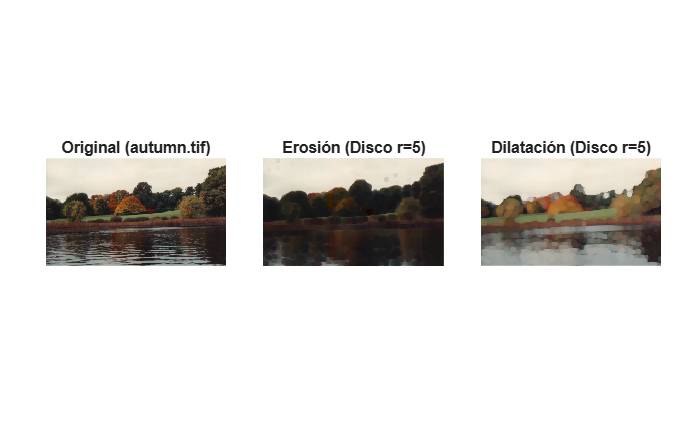

I_autumn_ero = imerode(I_autumn, SE_disk5);
I_autumn_dil = imdilate(I_autumn, SE_disk5);
figure('Name', '3. Morfología sobre Imagen RGB (autumn.tif)');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_autumn);     title('Original (autumn.tif)');
nexttile; imshow(I_autumn_ero); title('Erosión (Disco r=5)');
nexttile; imshow(I_autumn_dil); title('Dilatación (Disco r=5)');

Además, se pide: 

- Ejecute el programa cargando la imagen en escala de grises `'rice.png' `y  la imagen binaria `'circles.png'`. Observe el comportamiento de los operadores morfológicos sobre los distintos tipos de imágenes.¿Qué diferencias ve? 

- Elementos estructurantes. Observe el efecto de las operaciones morfológicas utilizadas en (3) con elementos estructurantes de diferentes formas y tamaños (ver ayuda: [https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).](https://es.mathworks.com/help/images/ref/strel.html?s_tid=doc_ta).)

- Operadores morfológicos. Cargue la imagen en escala de grises `'rice.png' `y realice una operación de umbralizado con la función `imbinarize`, que por defecto utiliza el método de Otsu. Utilice las funciones `imclose` o `imopen` para eliminar los pequeños píxeles aislados que puedan estar en el fondo de la imagen. Tenga en cuenta que el tipo y tamaño del elemento estructurante debe ser ajustado.

- Repita la pregunta anterior pero utilizando la imagen original complementada (utilice la función `imcomplement`).

- Comente las diferencias en el efecto sobre los detalles en la imagen original y en la complementada.

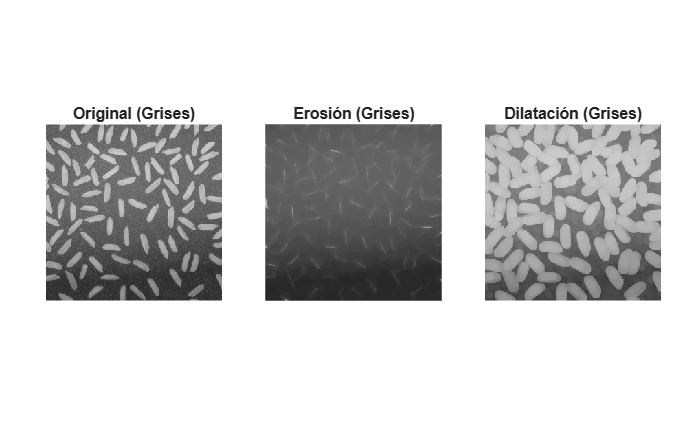

%% Pregunta 1: Morfologia sobre escala de grises
SE_disk5 = strel('disk', 5);
I_rice = imread('rice.png');
I_circ = imread('circles.png');
% Erosion y dilatacion a escala de grises
I_rice_ero = imerode(I_rice, SE_disk5);
I_rice_dil = imdilate(I_rice, SE_disk5);
% Erosion y dilatacion binario
I_circ_ero = imerode(I_circ, SE_disk5);
I_circ_dil = imdilate(I_circ, SE_disk5);

% Visualización en escala de grises
figure('Name', 'P1. Morfología en Escala de Grises (rice.png)');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(I_rice);     title('Original (Grises)');
nexttile; imshow(I_rice_ero); title('Erosión (Grises)');
nexttile; imshow(I_rice_dil); title('Dilatación (Grises)');

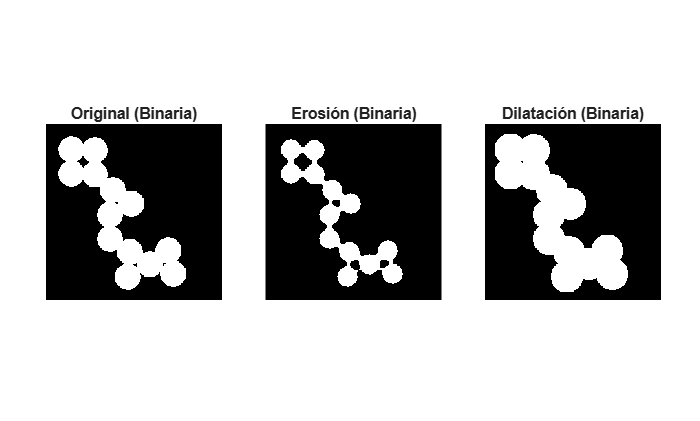


% Visualización en binario
figure('Name', 'P1. Morfología en Imagen Binaria (circles.png)');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(I_circ);     title('Original (Binaria)');
nexttile; imshow(I_circ_ero); title('Erosión (Binaria)');
nexttile; imshow(I_circ_dil); title('Dilatación (Binaria)');

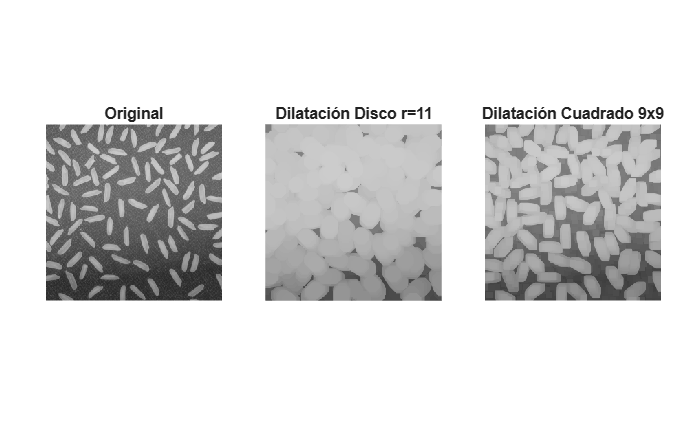


%% Pregunta 2. Comparativa de elementos estructurantes

SE_disk11 = strel('disk', 11);
SE_square = strel('square', 9);

I_rice_dil_disk11 = imdilate(I_rice, SE_disk11);
I_rice_dil_square = imdilate(I_rice, SE_square);

figure('Name', 'P2. Comparativa de Elementos Estructurantes');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(I_rice);            title('Original');
nexttile; imshow(I_rice_dil_disk11); title('Dilatación Disco r=11');
nexttile; imshow(I_rice_dil_square); title('Dilatación Cuadrado 9x9');

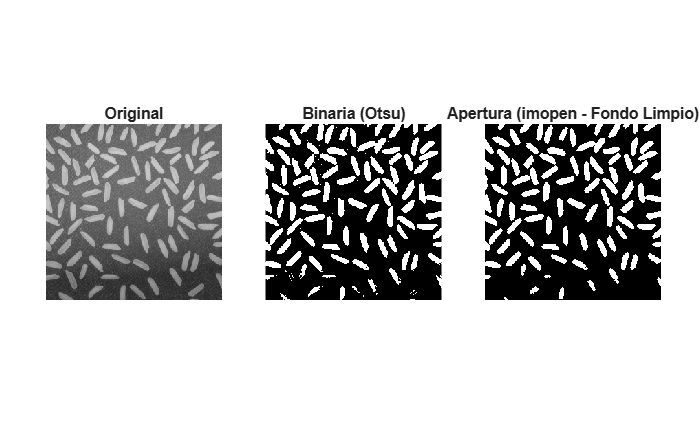


%% Pregunta 3. Umbralizacion de 'rice.png' y limpieza

I_rice_bin = imbinarize(I_rice);
% Erosion y dilatacion para eliminar el ruido fino
SE_clean = strel('disk', 2);
I_rice_open = imopen(I_rice_bin, SE_clean);

figure('Name', 'P3. Umbralizado y Limpieza de Fondo (rice.png)');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
nexttile; imshow(I_rice);      title('Original');
nexttile; imshow(I_rice_bin);  title('Binaria (Otsu)');
nexttile; imshow(I_rice_open); title('Apertura (imopen - Fondo Limpio)');

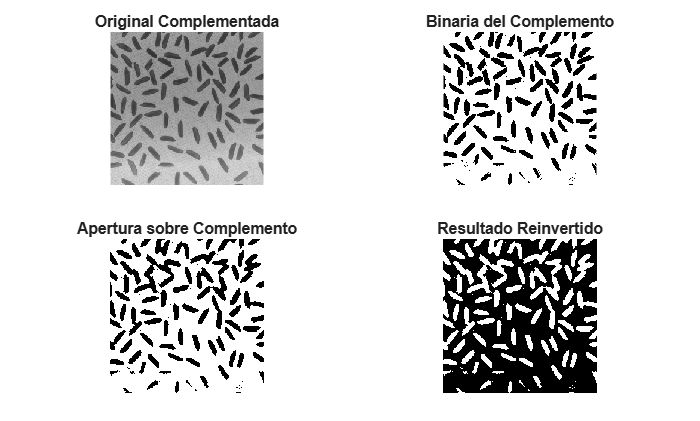


%% Pregunta 4 y 5. Procesamiento sobre la imagen complementada.

I_rice_comp = imcomplement(I_rice);
I_rice_comp_bin = imbinarize(I_rice_comp);
I_rice_comp_clean = imopen(I_rice_comp_bin, SE_clean);
figure('Name', 'P4 y P5. Procesamiento sobre Imagen Complementada');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_rice_comp);      title('Original Complementada');
nexttile; imshow(I_rice_comp_bin);  title('Binaria del Complemento');
nexttile; imshow(I_rice_comp_clean);title('Apertura sobre Complemento');
nexttile; imshow(imcomplement(I_rice_comp_clean)); title('Resultado Reinvertido');

Dada la imagen "HuellaOrig.jpg", que presenta ruido (tanto puntos negros dentro de la huella, como puntos blancos por fuera), se pide:

- Crear una imagen en la que se hayan eliminado los puntos blancos de ruido,

- A partir de dicha imagen, eliminar también los puntos negros dentro de la huella, para generar una imagen limpia. 

- Elegir y justificar el tipo y tamaño del elemento estructurante y las operaciones morfológicas utilizadas.

- Mostrar conjuntamente:

- imagen original; 

- resultado después de eliminar los puntos blancos; 

- resultado final después de eliminar también los puntos negros.

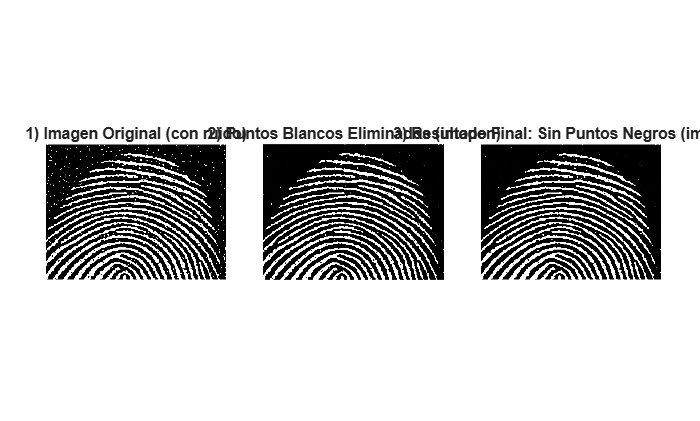

clearvars -except I_rgb X_ind map_ind Igris I_avion I_mat I_cell I_saturno I_card;


I_huella = imread('HuellaOrig.jpg');
if size(I_huella, 3) == 3
    I_huella = rgb2gray(I_huella);
end

% Un radio de 2 a 3 pixeles es ideal porque es mayor que el tamaño de los
% puntos de ruido aislados, pero menor que el grosor de las lineas/crestas
% de la huella.
r_se = 2;
SE_huella = strel('disk', r_se);
% imopen erosion + dilatacion. Elimina objetos claros mas pequeños que el
% SE.
I_sin_blancos = imopen(I_huella, SE_huella);
% imclose dilatacion + erosion. Rellena huecos/agujeros oscuros dentro de
% zonas claras.
I_huella_limpia = imclose(I_sin_blancos, SE_huella);

%% Visualización Conjunta (3 imágenes)
figure('Name', 'Filtrado Morfológico de Huella Dactilar');
tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_huella);
title('1) Imagen Original (con ruido)');

nexttile; imshow(I_sin_blancos);
title('2) Puntos Blancos Eliminados (imopen)');

nexttile; imshow(I_huella_limpia);
title('3) Resultado Final: Sin Puntos Negros (imclose)');

Dado el siguiente código:

Se pide: 

- Suponga que solo interesan las estrellas pequeñas y que se desea eliminar la contribución de la galaxia. Las estrellas presentan tamaños del orden de unos pocos píxeles (aproximadamente 2–6 píxeles de radio), mientras que la galaxia presenta dimensiones muy superiores. Pruebe distintos radios para un elemento estructurante en forma de disco y determine experimentalmente un tamaño que permita conservar las estrellas pequeñas y eliminar la galaxia.

- Cuando el fondo es blanco y el primer plano es oscuro, debemos cambiar el enfoque. Obtenga la imagen complementada con la función `imcomplement. `Aplique sobre ella la transformación *white top-hat* utilizada anteriormente y observe el resultado. ¿Por qué deja de ser adecuada esta operación para extraer las estrellas? Determine qué operación morfológica resulta ahora apropiada para extraer estructuras pequeñas más oscuras que su entorno, aplíquela y muestre el resultado.

clearvars -except I_rgb X_ind map_ind Igris I_avion I_mat I_cell I_saturno I_card I_huella;
close all; clc;

Step 1) Reading the Image

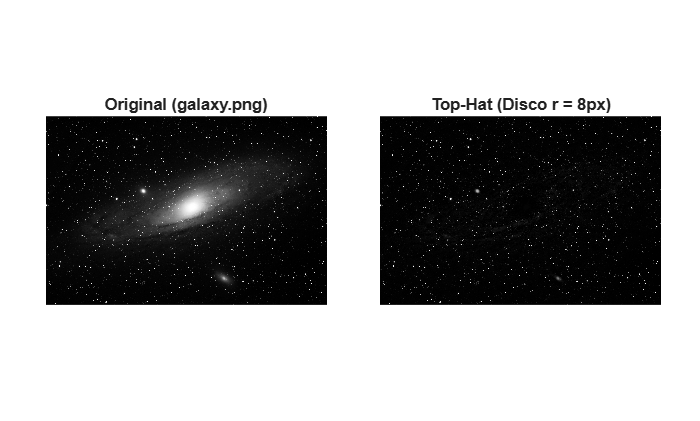

I_gal = imread('galaxy.png');
if size(I_gal, 3) == 3
    I_gal =rgb2gray(I_gal);
end
%% Pregunta 1. 
% Como las estrellas tienen un radio aproximado de 2 a 6 pixeles, un disco
% con radio r_se_gal = 8 o 10 pixeles es suficiente para "borrarlas" en la
% apertura.

r_estrellas = 8;
SE_gal = strel('disk', r_estrellas);

I_tophat = imtophat(I_gal, SE_gal);
figure('Name', 'P1. Top-Hat en Imagen Original (Fondo Oscuro)');
tiledlayout(1, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_gal);
title('Original (galaxy.png)');

nexttile; imshow(I_tophat);
title(['Top-Hat (Disco r = ', num2str(r_estrellas), 'px)']);

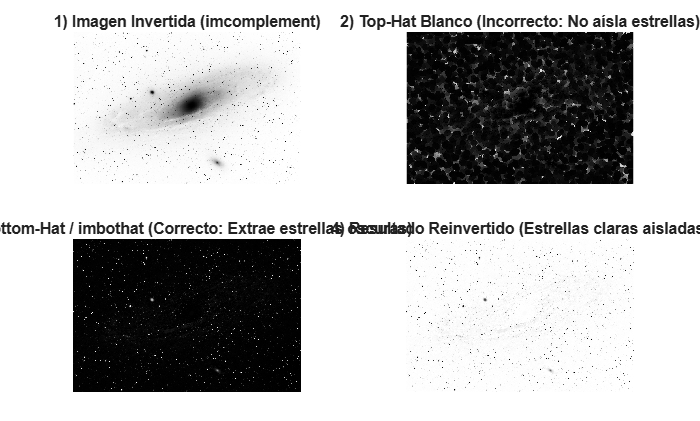

%% Pregunta 2.
% Obtener la imagen complementada (fondo blanco, estrellas oscuras)
I_gal_comp = imcomplement(I_gal);
% Si aplicamos white top-hat sobre el complemento, no detecta las estrellas
% oscuras
I_tophat_comp_incorrecto = imtophat(I_gal_comp, SE_gal);
% La operacion correcta para estructuras oscuras en fondo claro es
% Bottom-hat
I_bothat_correcto = imbothat(I_gal_comp, SE_gal);
% Visualización comparativa de la Pregunta 2
figure('Name', 'P2. Procesamiento sobre Imagen Invertida');
tiledlayout(2, 2, 'TileSpacing', 'compact', 'Padding', 'compact');

nexttile; imshow(I_gal_comp);
title('1) Imagen Invertida (imcomplement)');

nexttile; imshow(I_tophat_comp_incorrecto);
title({'2) Top-Hat Blanco (Incorrecto: No aísla estrellas)'});

nexttile; imshow(I_bothat_correcto);
title({'3) Bottom-Hat / imbothat (Correcto: Extrae estrellas oscuras)'});

nexttile; imshow(imcomplement(I_bothat_correcto));
title({'4) Resultado Reinvertido (Estrellas claras aisladas)'});